# Unevenly Lit images

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

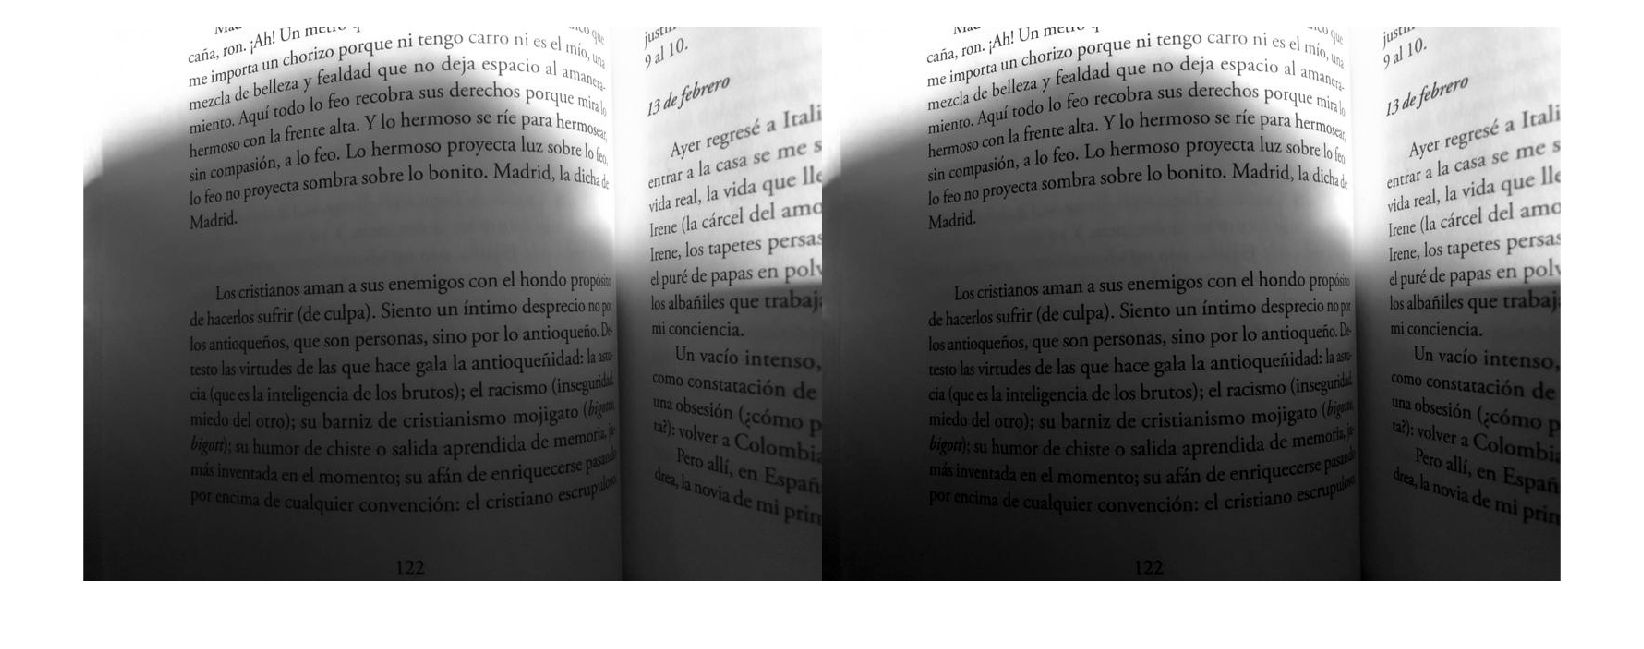

book = imread("./images/book.jpg");
book = im2gray(book);
imshowpair(book, imadjust(book), "montage")

## Task 1

The `histeq` function performs histogram equalization. If no reference histogram is given, `histeq` uses the uniform distribution.

`Ieq` `=` `histeq``(``I``)``;`

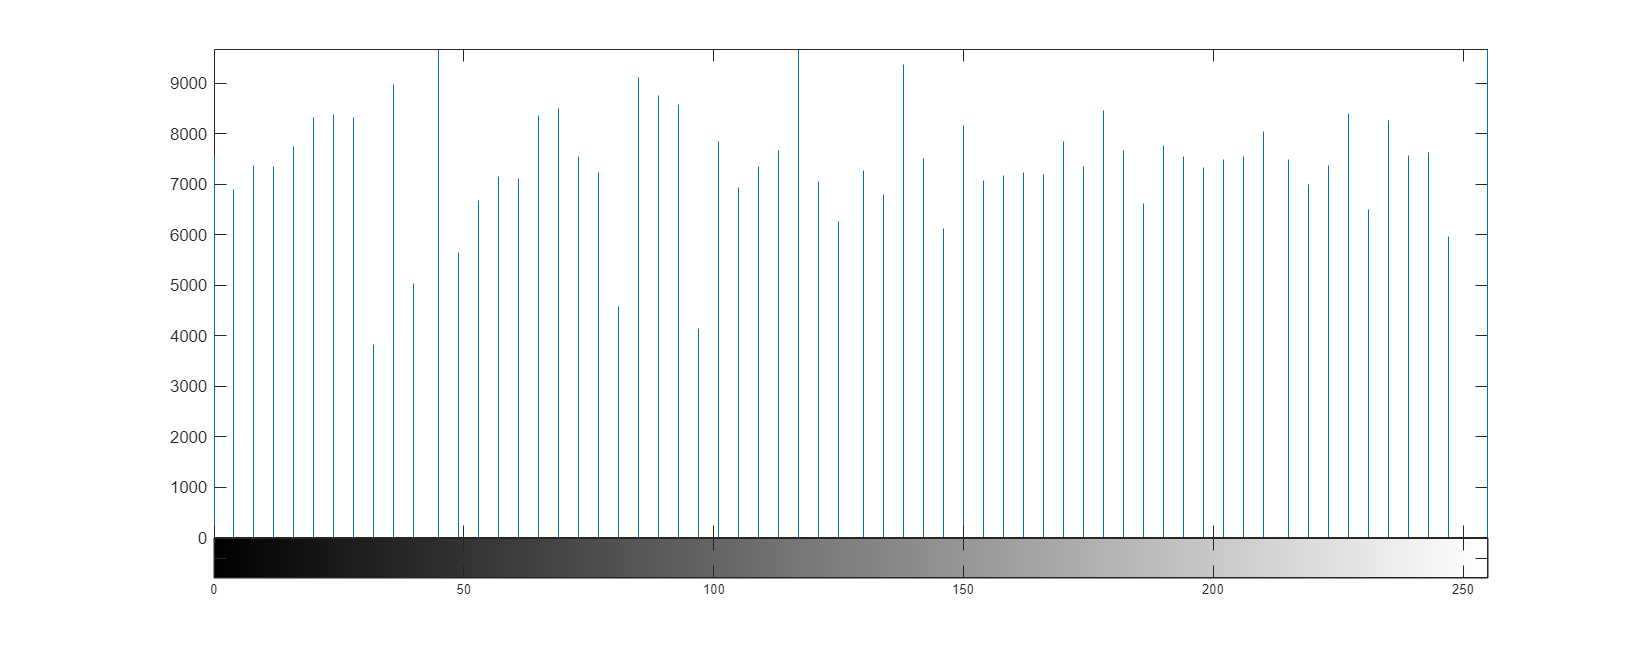

bookEq = histeq(book);
imhist(bookEq)

## Task 2

While not perfectly uniform, the equalized histogram does approximate a uniform distribution. Did this improve the image contrast? 

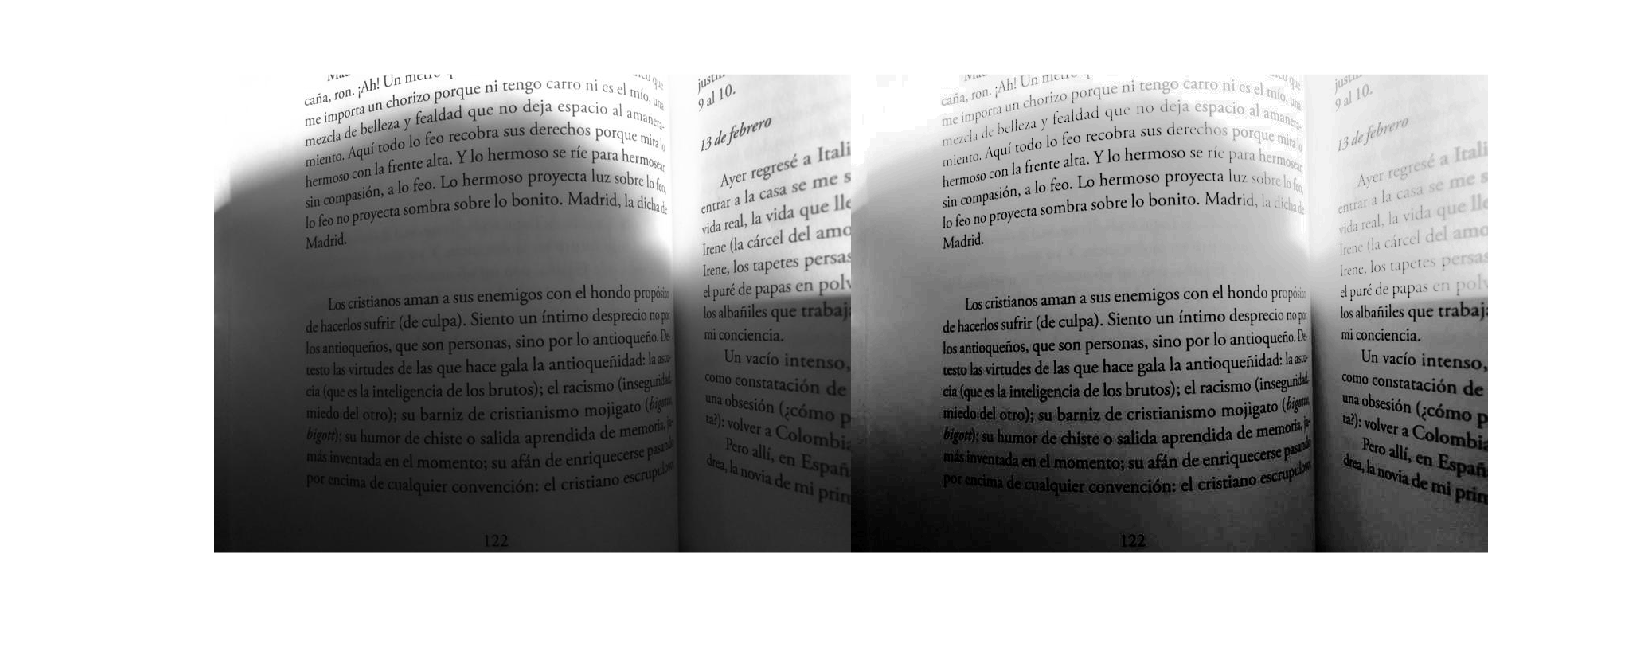

imshowpair(book, bookEq, "montage")

## Task 3

The text on the page is easier to read, so the equalization did improve the contrast between the text and paper.

The `histeq` function equalizes the histogram of the entire image. Because different parts of this image have different distributions of intensities, it would likely benefit from *adaptive* histogram equalization.

An adaptive method performs equalization locally rather than globally. You can use the `adapthisteq` function to perform adaptive histogram equalization.

`Iadapt` `=` `adapthisteq``(``I``)``;`

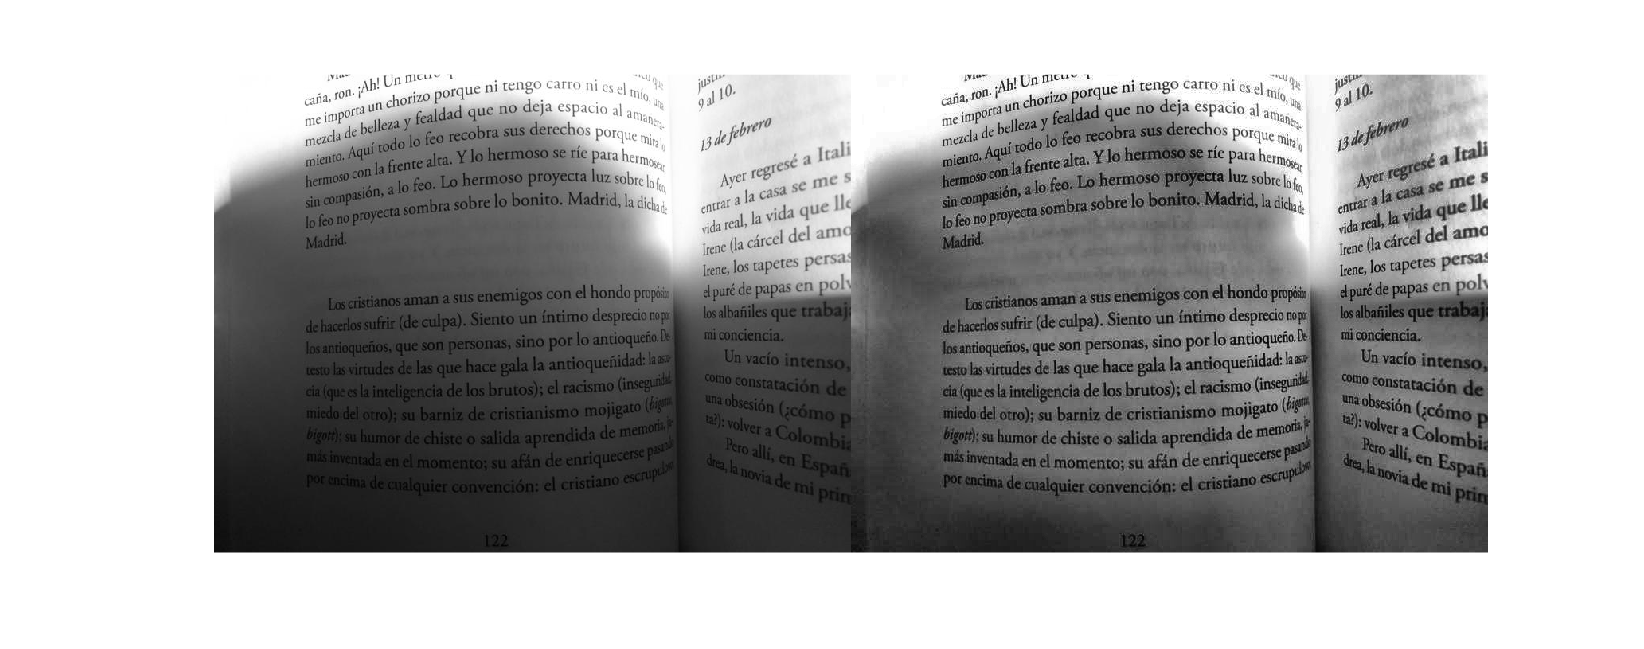

bookAdapt = adapthisteq(book);
imshowpair(book, bookAdapt, "montage")